clc; clear; close all;

%% Input image
img = readFrame(VideoReader("coin_1.mp4"));

%%Image processing

img_grayscale = im2gray(img); %convert to grayscale

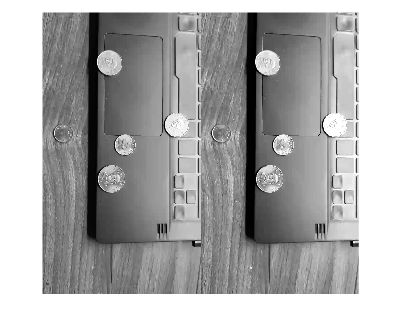

img_grayscale_adj = imadjust(img_grayscale); %balance constras
imshowpair(img_grayscale, img_grayscale_adj, "montage");

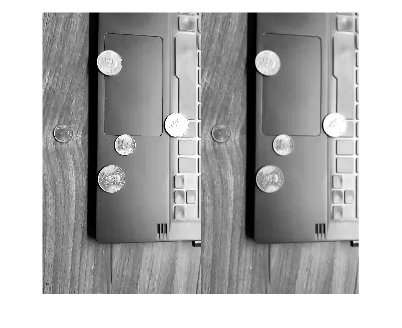

noise_filter = fspecial("average", 5); %create a average filter 3x3 -> noise reduction
img_grayscale_smooth = imfilter(img_grayscale_adj, noise_filter, "replicate");
%img_grayscale_smooth = imgaussfilt(img_grayscale_adj,2);

imshowpair(img_grayscale_adj, img_grayscale_smooth, "montage");

bw = imbinarize(img_grayscale_smooth, "adaptive")

bw = 1280×720 logical array
   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0
   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0
   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0
   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0
   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

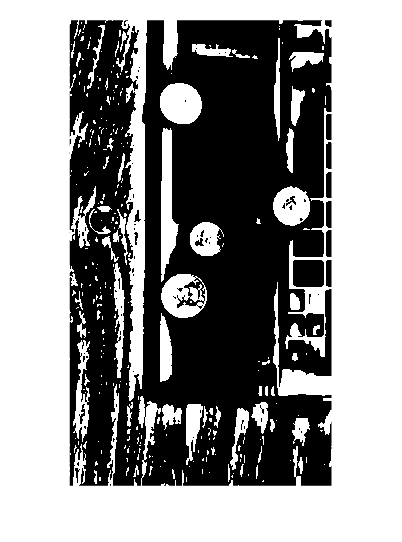

imshow(bw)

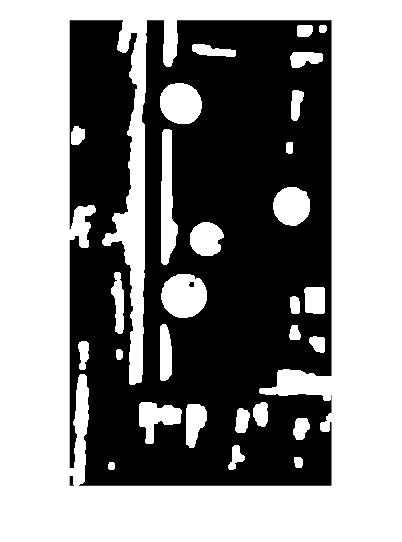

bw = imclose(bw, strel("disk", 6));
bw = imopen(bw, strel("disk", 10));


**BOUDING BOX/CENTROID**

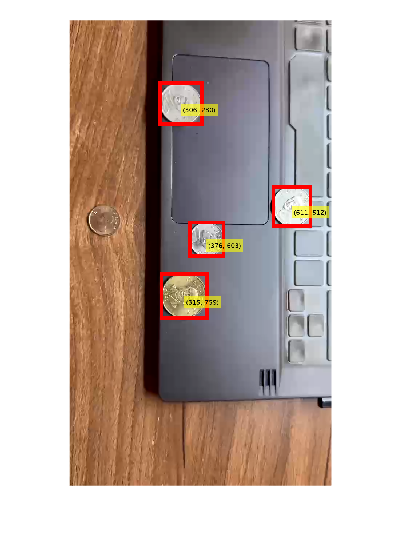

%%Image BoundingBox/Centroid 

stats = regionprops(bw, 'BoundingBox', 'Centroid', "Eccentricity", "Area");
im_binary_out  = img;

for k = 1:length(stats)
    if stats(k).Eccentricity < 0.4 && stats(k).Area > 1000
    box = stats(k).BoundingBox;
    centroid = stats(k).Centroid;
    im_binary_out = insertShape(im_binary_out, 'Rectangle', box, 'Color', 'red', 'LineWidth', 10);
    coordText = sprintf('(%d, %d)', round(centroid(1)), round(centroid(2)));
    im_binary_out = insertText(im_binary_out, centroid, coordText, 'FontSize', 18, 'BoxColor', 'yellow');
    end
end
imshow(im_binary_out);